This is a demo for the regularization chapter of deep learning book club. 

This example includes how different kinds of regularization methods can be utilized for Deep Learning. 

Examples Covered: 

- Using NN on MNSIT Data

- Using CNN on MNIST Data

- Parameter Norm Penalities with CNNs vs NNs -- with L2 and L1 parameter norms

- Constrained Optimization

- Underconstrained Optimizations - Pseudo Inverse

- Dataset Augmentation

- Noise at the Output Targets

- Early Stopping

- Parameter Sharing - CNNs

- Sparse Representations - OptShrink etc

- Bagging

- Adversarial Trainng

**Neural Network:  the classification of MNIST digits**

**Idea:  **Vectorize the pixels and apply a neural network on it. 

in the Image below - Batch Size is 500, not epoch size

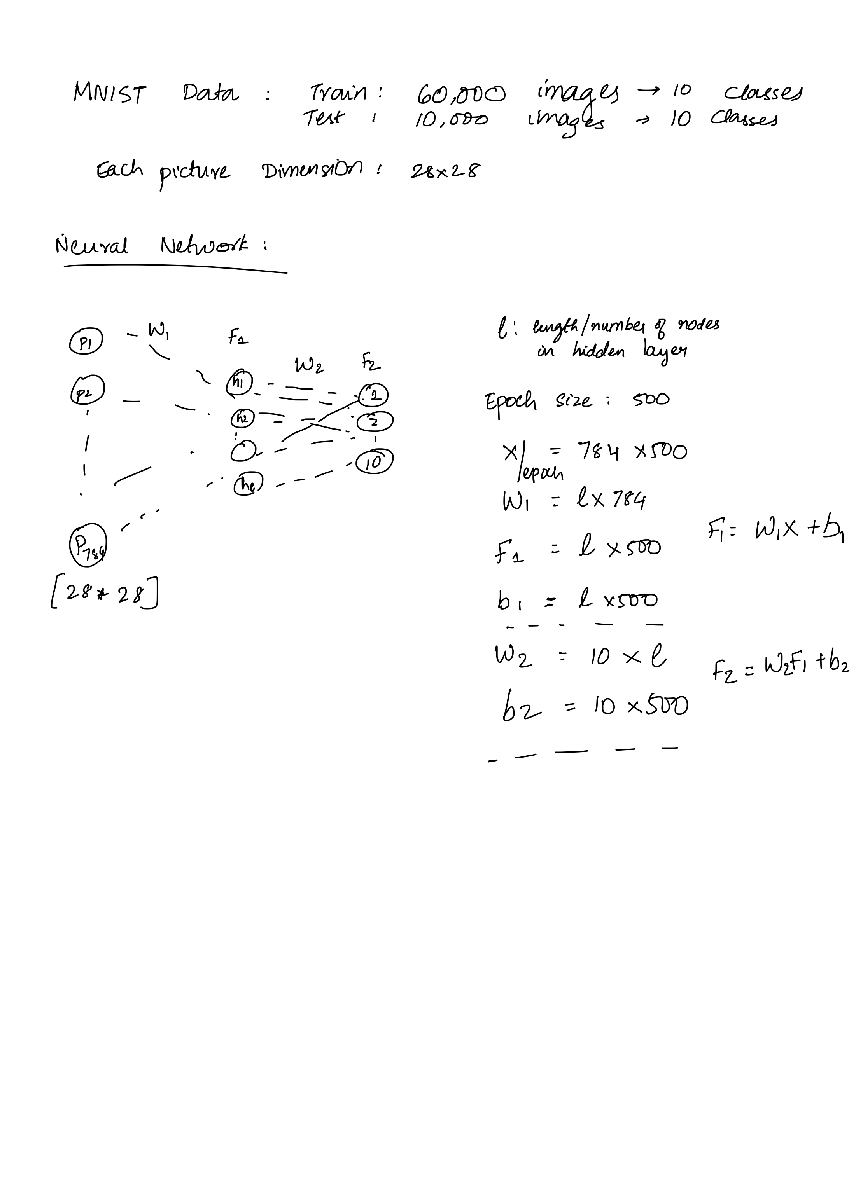

Parameters: 

- Input layer:   

%Defining the sizes of parameters

% trainImageVecs = loadMNISTImages('train-images-idx3-ubyte',true);
% trainLabels = loadMNISTLabels('train-labels-idx1-ubyte') + 1;
% 
% testImageVecs = loadMNISTImages('t10k-images-idx3-ubyte',true);
% testLabels = loadMNISTLabels('t10k-labels-idx1-ubyte') +1 ;
load daaata.mat

%Tweaks on the neural network for experimental usage 

%Flip this switch to true to see how turning activation on affects the
%neural network
hasActivation = true;

%Flip this switch to true to see how randomized data in batches for every epoch affects your neural network
doRandomizedBatches = false;

%Select between the following activation functions   
% % https://towardsdatascience.com/activation-functions-neural-networks-1cbd9f8d91d6
% 1. Sigmoid
% 2. Hyperbolic Tangent
% 3. Rectified Linear Unit
% 4. Leaky ReLU
% 5. Exponential 
% 6. Exponential linear unit

layer1_activationFunction = 2;
layer2_activationFunction = 5;



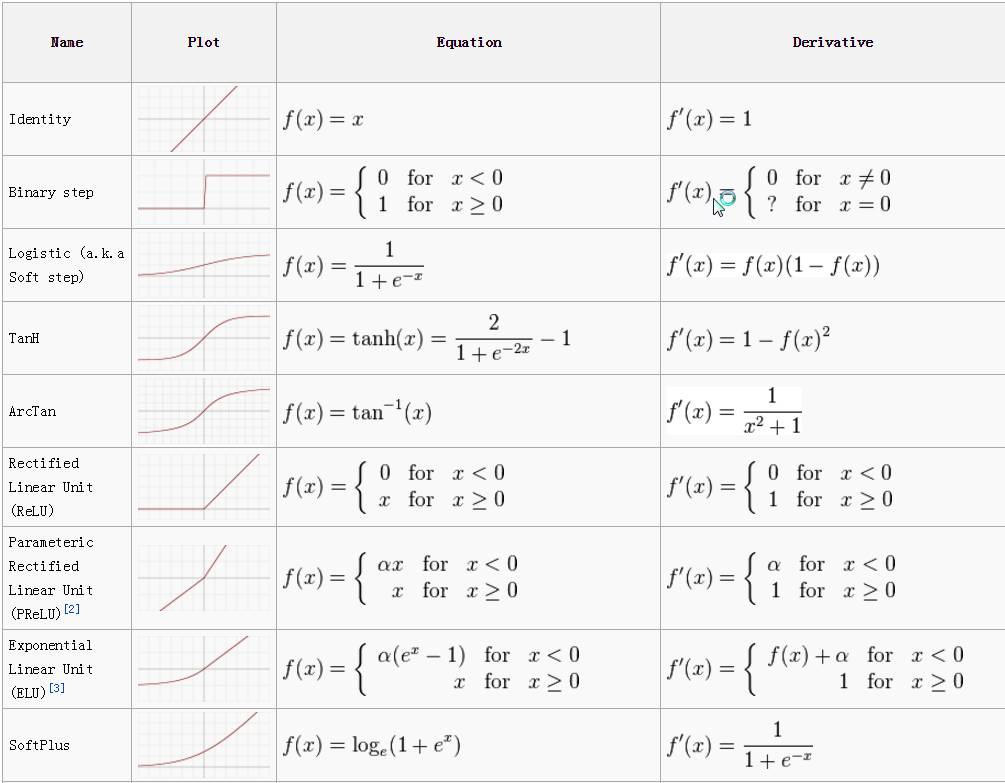

%Setting the network parameters

[dim, num_data] = size(trainImageVecs);
[~, num_tdata] = size(testImageVecs);

num_epoch = 100;
batch_size = 500;
num_hidden_1 = 50;
num_output = 10;

test_batch_size = 1000;



% basic setting
% xavier's method to initialize weights : Why does this matter? 
% https://prateekvjoshi.com/2016/03/29/understanding-xavier-initialization-in-deep-neural-networks/
% TL;DR:  We need to pick the weights from a Gaussian distribution
%         with zero mean and a variance of 1/N, where N specifies the number of input neurons.
% initialize in such a way that variance of W1 is 1/(Nin + Nout) = 0.0025
r1 = sqrt(6) / sqrt(dim + num_hidden_1);
w1 = rand(num_hidden_1, dim)*2*r1 - r1; 
b1 = zeros(num_hidden_1, 1);

r2 = sqrt(6) / sqrt(num_hidden_1 + num_output);
w2 = rand(num_output, num_hidden_1)*2*r2 - r2;
b2 = zeros(num_output, 1);


## Initializing learning rates for w,b terms


lr_w = 2;
lr_b =  2;
gam = 0.5

% loss/acc history
loss_list = zeros(num_epoch, 1);
acc_list = zeros(num_epoch, 1);
tloss_list = zeros(num_epoch, 1);
tacc_list = zeros(num_epoch, 1);

for i = 1: num_epoch
    if doRandomizedBatches
        rp =  randperm(num_data); %To randomize the data picked up as batches in every epoch - 1x60000

gam =    0.500000000000000


    else
        rp = 1:num_data;
    end
    for batch_ind =  1: batch_size : num_data-batch_size+1
        X_batch =  trainImageVecs(:, rp(batch_ind:batch_ind+batch_size-1));
        labels_batch = trainLabels(rp(batch_ind:batch_ind+batch_size-1));
        
        %%%% FEED FORWARD LAYER %%%%%
        F1 =  w1 * X_batch + b1 ;
        
        if hasActivation
            func = getActivationFunction(layer1_activationFunction);
            F1 =  func(F1);
        end
        
        F2 =  w2 * F1 + b2 ;
        
        if hasActivation
             %Exponent because the values range from 0-9 
             func = getActivationFunction(layer2_activationFunction);
             F2 =  func(F2);
        end
        
        normalizedProbsF2 = F2./sum(F2,1); 
        
        
        % compute the error
        I = sub2ind(size(normalizedProbsF2), labels_batch', 1:batch_size);
        p = zeros(size(normalizedProbsF2));
        p(I) = 1; % assign 1 only on where 'labels' indicate
        err2 = (normalizedProbsF2 - p)/batch_size;
        
        %%%% Back Propagation %%%%
        
        grad2_w = err2 * F1';
        grad2_b = sum(err2, 2);
        c1 = w2' * err2;
        err1 = c1 .* F1 .* (1-F1);
        
        grad1_w = err1 * X_batch';
        grad1_b = sum(err1, 2);
        
        % update the weights.
        % each weight and bias should be updated
        % with its gradient and lr_w and lr_b
        w2 = w2 - lr_w*grad2_w;
        b2 = b2 - lr_b*grad2_b;
        w1 = w1 - lr_w*grad1_w;
        b1 = b1 - lr_b*grad1_b;
        %%%%
    end
    
      % decay
    if ~mod(i, 40)
        lr_w = lr_w * gam;
        lr_b = lr_b * gam;
    end
    
     % record the training loss and accuracy
    loss_list(i) = -sum(log(normalizedProbsF2(I)))/batch_size;
    [~, pred_labels] = max(normalizedProbsF2);
    acc_list(i) = length(find(pred_labels == labels_batch'))/batch_size;

    % get the test output
    tf1 = w1*testImageVecs+b1;
    tf1 = internal_sigmoid(tf1);
    tf2 = w2*tf1 + b2;
    ts = exp(tf2);
    ts =  ts ./ sum(ts,1);
 
    
    % get the test result and record it
    I = sub2ind(size(ts), testLabels', 1:num_tdata);
    tloss_list(i) = -sum(log(ts(I)))/num_tdata;
    [~, tpred_labels] = max(ts);
    

    tacc_list(i) = length(find(tpred_labels == testLabels'))/num_tdata;
    
    
    
    
end


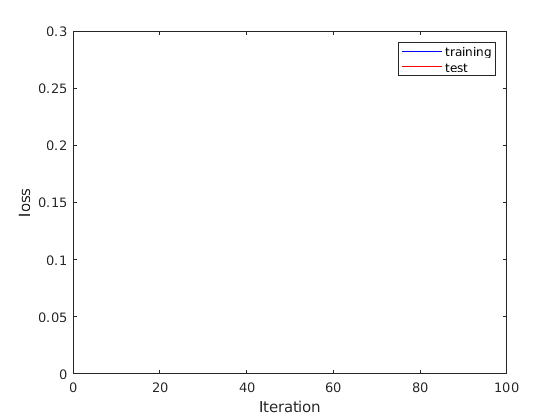

figure(3)
plot(1:num_epoch, loss_list, 'b-'); hold on;
plot(1:num_epoch, tloss_list, 'r-');
xlabel('Iteration'); ylabel('loss');
legend('training', 'test');
xlim([0.0 100.0])
ylim([0.000 0.300])

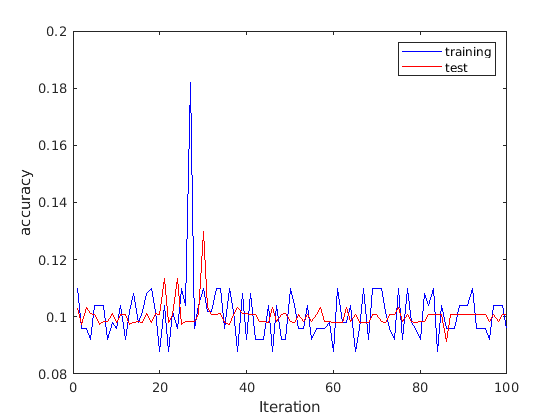


figure(4)
plot(1:num_epoch, acc_list, 'b-'); hold on;
plot(1:num_epoch, tacc_list, 'r-');
xlabel('Iteration'); ylabel('accuracy');
legend('training', 'test');